## A

fs = 8000;
duration = 0.1;
gap = 0.1;
[~,z_1] = generate_wave({"1"},fs,duration,gap);
[~,z_5] = generate_wave({"5"},fs,duration,gap);
[~,z_9] = generate_wave({"9"},fs,duration,gap);
[t_total,z_D] = generate_wave({"D"},fs,duration,gap);

### 1

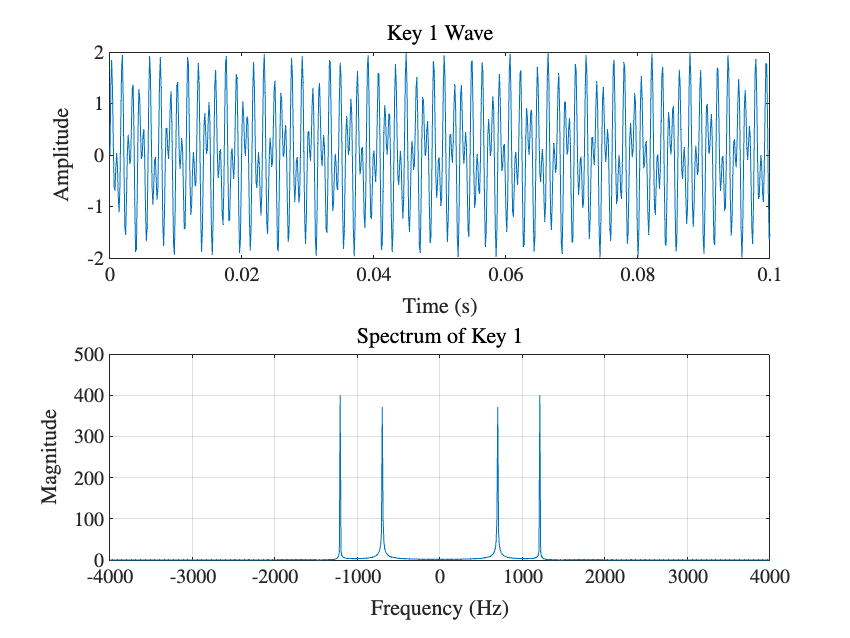

figure;
subplot(2,1,1)
plot(t_total, z_1);
title("Key 1 Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z_1);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of Key 1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

print('TeX/images/4A1.eps', '-depsc');

### 5

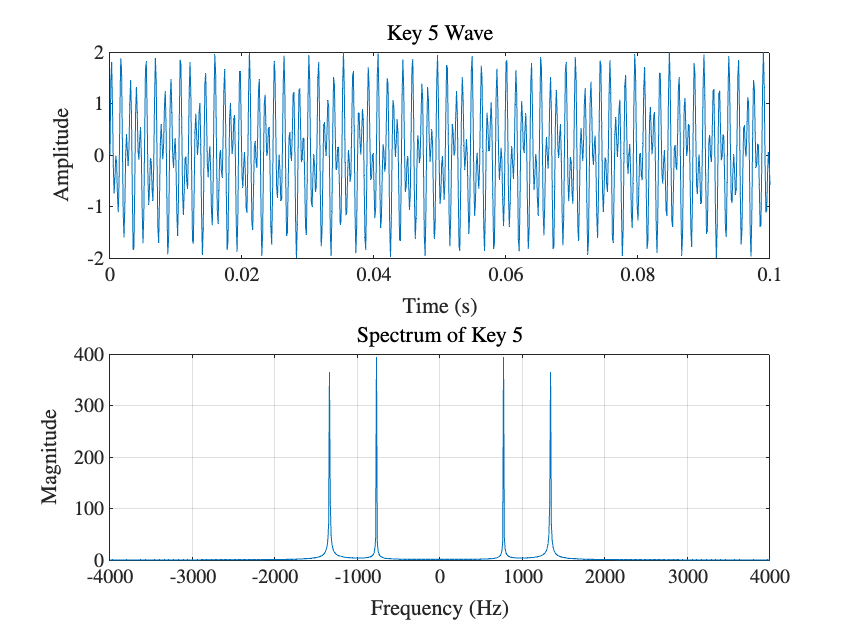

figure;
subplot(2,1,1)
plot(t_total, z_5);
title("Key 5 Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z_5);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of Key 5');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

print('TeX/images/4A5.eps', '-depsc');

### 9

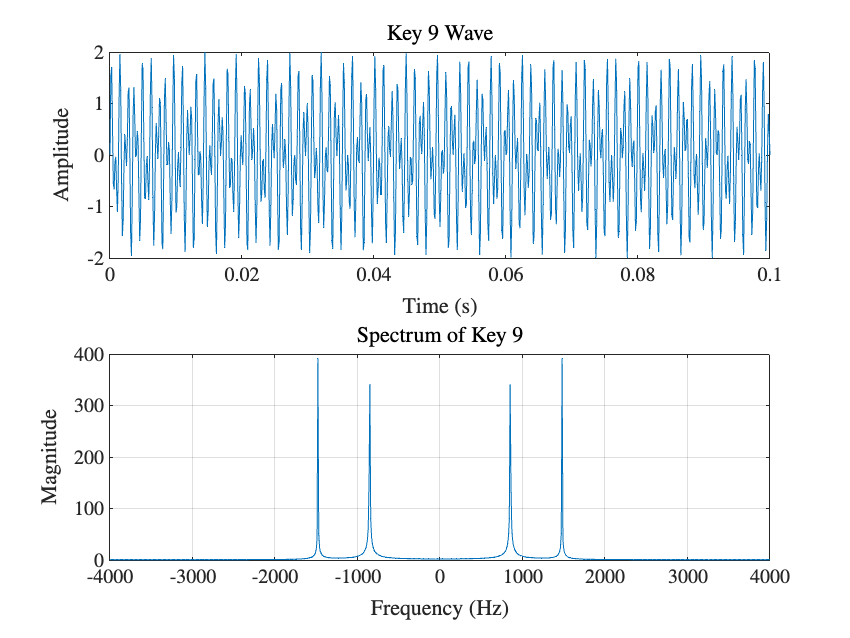

figure;
subplot(2,1,1)
plot(t_total, z_9);
title("Key 9 Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z_9);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of Key 9');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

print('TeX/images/4A9.eps', '-depsc');

### D

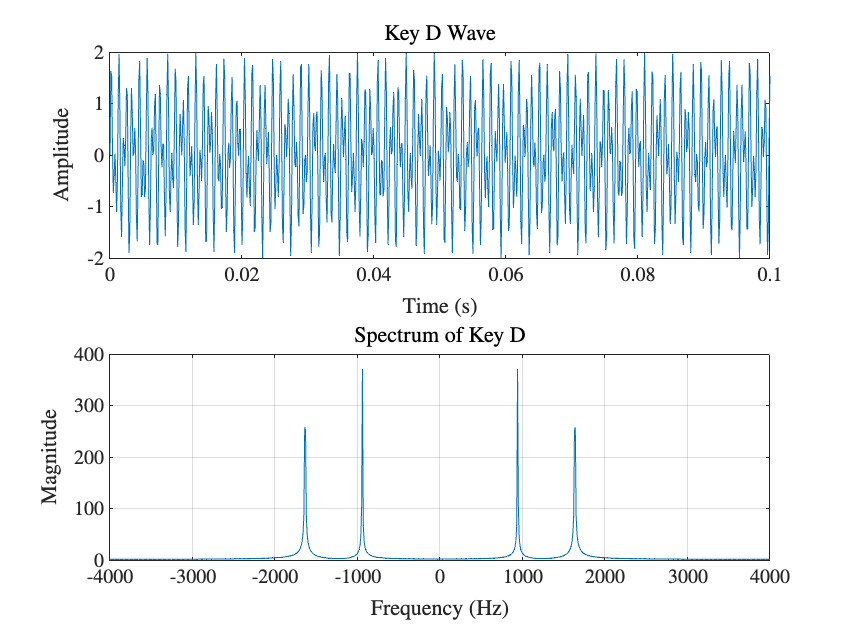

figure;
subplot(2,1,1)
plot(t_total, z_D);
title("Key D Wave");
xlabel("Time (s)");
ylabel("Amplitude");

key_spectra = fft(z_D);

subplot(2,1,2)
f_output = linspace(-fs/2, fs/2, length(key_spectra));
plot(f_output, (abs(fftshift(key_spectra))));
grid on
title('Spectrum of Key D');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

print('TeX/images/4AD.eps', '-depsc');